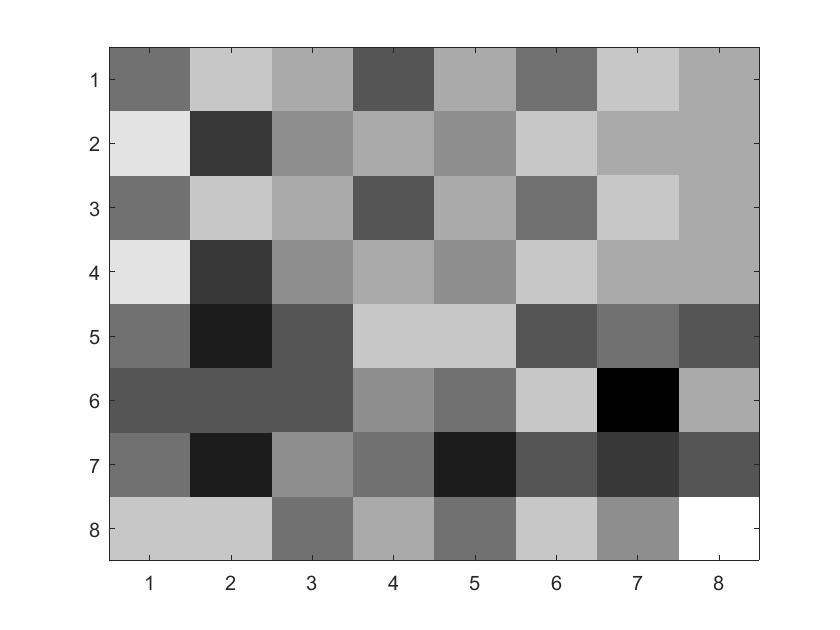

clear
close all

p = 8; % patch size
M = p^2; % number of element in the patch

% load the cameraman image
img = im2double(imread('C:\Users\simo9\Desktop\MMMIP\lez2_orth_basis_imgs\matlab\cameraman.png'));


% extract a patch from the image
s_block = img(1:p, 1:p);
% should we keep a particular order when unrolling?
% unroll the patch
s = reshape(s_block, 1, [])';

% show the patch
imagesc(s_block)
colormap(gray)

## compute the 2D DCT matrix (M x M)

D = zeros(M);
for ii=1:M
    % define the atom
    a = zeros(1, M);
    a(ii) = 1;
    a = reshape(a, [p,p]);
    temp2 = idct2(a')';
    D(:,ii) = reshape(temp2, [1,M]);
end
% verify that  D is orthonormal
is_D_orthonormal = D' * D%it looks like the identity.

is_D_orthonormal =     1.0000    0.0000    0.0000    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    1.0000    0.0000   -0.0000         0   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000

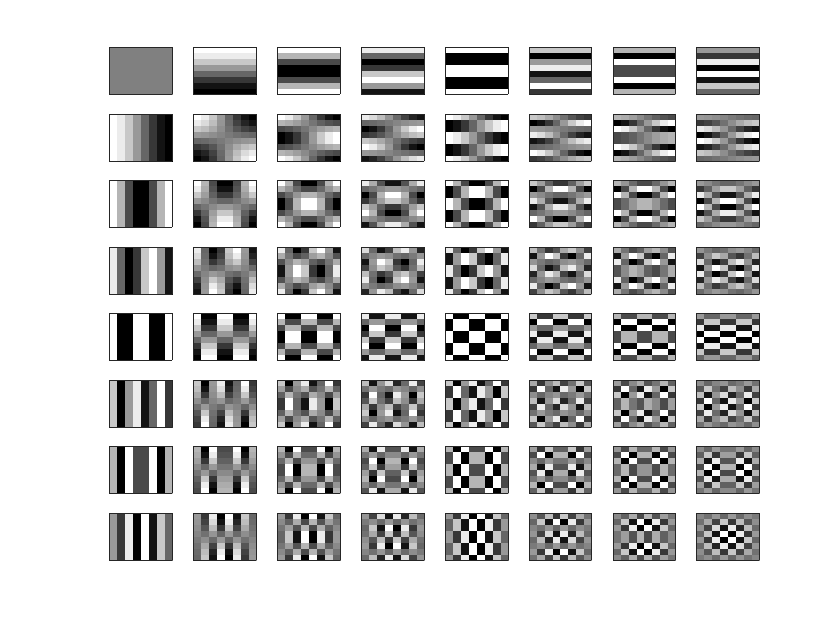

% Due to some approximation it isnt precisely equal to I

% all the atoms in D can be seen as patch. Let's plot them!
for ii=1:M
    subplot(p,p,ii);
    temp = D(:,ii);
    temp = reshape(temp, [p,p]);
    imagesc(temp)
    colormap(gray)
    set(gca,'xtick',[])
    set(gca,'ytick',[])
end



% compute the representation w.r.t. the 2D DCT matrix
x = D' * s;

## compute the separable 2D DCT

build the 1D DCT matrix

D1 = zeros(p);
for ii = 1:p
    a = zeros(1, p);
    a(ii) = 1;
    D1(:, ii) = idct(a)';
end %correct

% compute the 2D DCT exploiting the separability
x_block = D1' * s_block * D1% ok

x_block =     4.9211   -0.0077    0.0026    0.0018    0.0093    0.0041    0.0101   -0.0020
    0.0150   -0.0028    0.0021    0.0028   -0.0077    0.0008   -0.0090    0.0157
    0.0080    0.0020    0.0132   -0.0056   -0.0093   -0.0062   -0.0019   -0.0026
   -0.0196    0.0003   -0.0124   -0.0018    0.0036   -0.0036    0.0021   -0.0011
    0.0132   -0.0017    0.0013    0.0024    0.0034    0.0011   -0.0085    0.0021
   -0.0082    0.0036    0.0044   -0.0056   -0.0100    0.0002    0.0015    0.0056
    0.0078   -0.0029    0.0040   -0.0054   -0.0084   -0.0213   -0.0083   -0.0030
   -0.0112    0.0039   -0.0050   -0.0080   -0.0050   -0.0016   -0.0149    0.0123


x_block_giusta = reshape(Dgiusta' * s, [p,p])

x_block_giusta =     4.9211   -0.0077    0.0026    0.0018    0.0093    0.0041    0.0101   -0.0020
    0.0150   -0.0028    0.0021    0.0028   -0.0077    0.0008   -0.0090    0.0157
    0.0080    0.0020    0.0132   -0.0056   -0.0093   -0.0062   -0.0019   -0.0026
   -0.0196    0.0003   -0.0124   -0.0018    0.0036   -0.0036    0.0021   -0.0011
    0.0132   -0.0017    0.0013    0.0024    0.0034    0.0011   -0.0085    0.0021
   -0.0082    0.0036    0.0044   -0.0056   -0.0100    0.0002    0.0015    0.0056
    0.0078   -0.0029    0.0040   -0.0054   -0.0084   -0.0213   -0.0083   -0.0030
   -0.0112    0.0039   -0.0050   -0.0080   -0.0050   -0.0016   -0.0149    0.0123


x_block_D = reshape(D' * s, [p,p])%ok

x_block_D =     4.9211   -0.0077    0.0026    0.0018    0.0093    0.0041    0.0101   -0.0020
    0.0150   -0.0028    0.0021    0.0028   -0.0077    0.0008   -0.0090    0.0157
    0.0080    0.0020    0.0132   -0.0056   -0.0093   -0.0062   -0.0019   -0.0026
   -0.0196    0.0003   -0.0124   -0.0018    0.0036   -0.0036    0.0021   -0.0011
    0.0132   -0.0017    0.0013    0.0024    0.0034    0.0011   -0.0085    0.0021
   -0.0082    0.0036    0.0044   -0.0056   -0.0100    0.0002    0.0015    0.0056
    0.0078   -0.0029    0.0040   -0.0054   -0.0084   -0.0213   -0.0083   -0.0030
   -0.0112    0.0039   -0.0050   -0.0080   -0.0050   -0.0016   -0.0149    0.0123


% check if the coefficient computed using the two methods are equal
% is_coeff_equal = isequal(x_block, x_block_D)
% they are equal